25012601 양가인 MATLAB 과제 4주차

1.

clear;
clc;
fprintf('1번 문제:');

1번 문제:

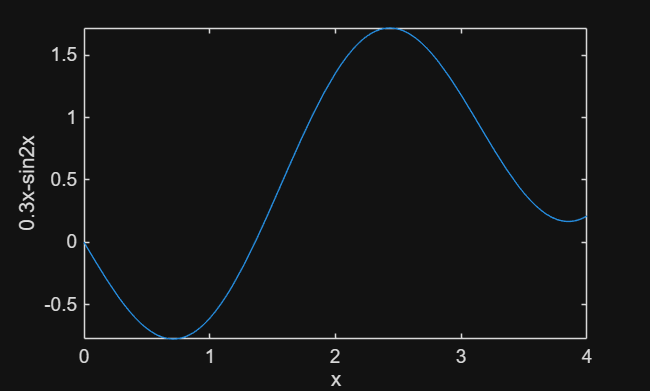


f1_1 = @(x) 0.3*x - sin(2*x);
f2_1 = @(x) 0.3 - 2*cos(2*x);%(d/dx)f1
fplot(f1_1, [0 4])
xlabel('x');
ylabel('0.3x-sin2x');

f1zero1_1 = fzero(f1_1, 0)%근1

f1zero1_1 = 0

f1zero2_1 = fzero(f1_1, 4)%근2

f1zero2_1 = 1.3606

min_1 = f1_1(fminbnd(f1_1, 0, 4))%최소값

min_1 = -0.7757


%최소증명
f2zero1 = fzero(f2_1, [0 1])%미분식의 해 구하기

f2zero1 = 0.7101

f2zero2 = fzero(f2_1, [1 3])

f2zero2 = 2.4315

f2zero3 = fzero(f2_1, [3 4])

f2zero3 = 3.8517


fprintf('minimum is ');%전체 최소값 = 극점의 최소값

minimum is 

disp(min([f1_1(f2zero1), f1_1(f2zero2), f1_1(f2zero3)]));

   -0.7757



disp(' ');

2.

h_2 = 100;
v0_2 = 50;
g = 9.81;
disp("2번 문제:");

2번 문제:


disp(ygn_25012601_func_2(h_2, v0_2, g));

    7.4612
    2.7324



50㎧의 속력으로 던져진 물체가 100m에 도달하는 시점은 각각 함수의 답으로 나온 2.7324와 7.4612이다.

물체의 높이는 시간에 대한 이차함수로 표현되기에 두 개의 답이 존재한다.

높이가 고점에 다다르는 시간은 (2.7324+7.4612)/2 = 5.0968 초임을 알 수 있다.

3 - (a)

h = 3V/πr²

A = πr  √(r² + (3V/πr²)²

3 - (b): 함수 파일에 선언(global V; A = pi.*R.*sqrt(R.^2 + ((3.*V)./(pi*R.^2)).^2);)

3 - (c)

global V;
V = 10; %(in³)
r_minA_3 = fminbnd(@ygn_25012601_func_3b, 0.1, 5)%면적 A를 최소화하는 r값

r_minA_3 = 1.8901

h_minA_3 = (3*V) / (pi*r_minA_3.^2)%면적 A를 최소화하는 r값에 상응하는 h값

h_minA_3 = 2.6730

disp("3번 문제");

3번 문제


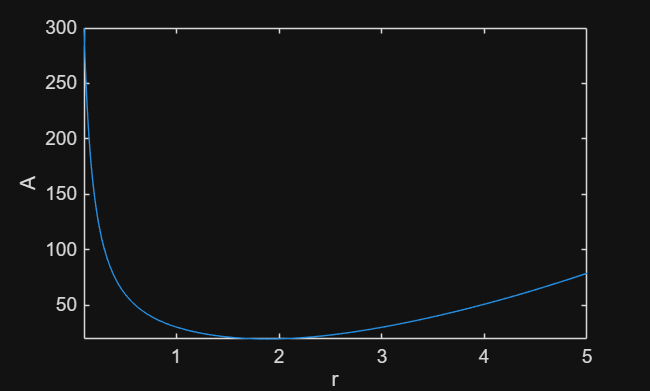

fplot(@ygn_25012601_func_3b, [0.1 5])
xlabel('r');
ylabel('A');

minAx110per_3 = (ygn_25012601_func_3b(r_minA_3))*110/100%면적최소값110%

minAx110per_3 = 21.3833

f3c = @(r) ygn_25012601_func_3b(r) - minAx110per_3;
disp("r의 면적 최소값*110% 증가 전까지 벗어날 수 있는 최대 범위:");

r의 면적 최소값*110% 증가 전까지 벗어날 수 있는 최대 범위:


disp(abs(fzero(f3c, r_minA_3) - r_minA_3));

    0.4078



disp(' ')

4.

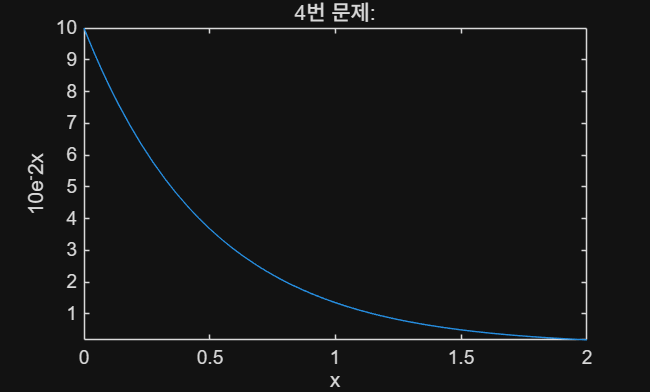

f4 = @(x) 10*exp(-2*x);

fplot(f4, [0 2])
title('4번 문제:');
xlabel('x');
ylabel("10e^-2x");

disp(' ');

5.

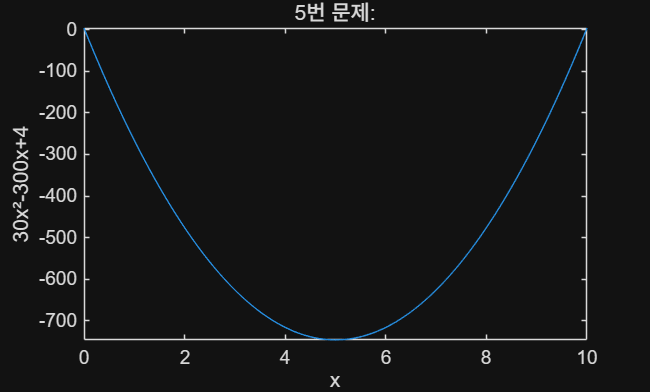

f5 = @(x) 30*x.^2 - 300.*x + 4;
%a
fplot(f5, [0 10]);
title("5번 문제:");
xlabel('x');
ylabel('30x²-300x+4');


%b
f5min = fminbnd(f5, 4.5, 5.5)

f5min = 5.0000

disp(' ');

6.

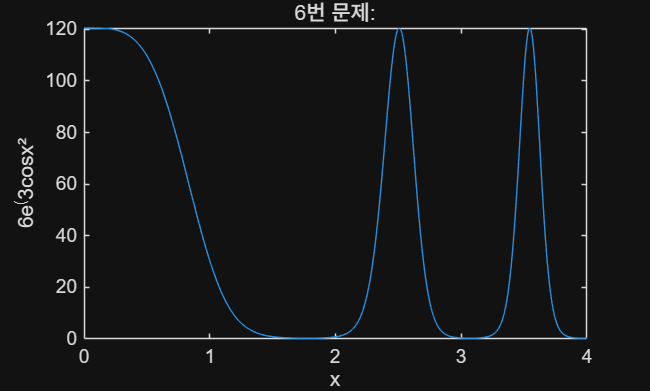

h = @(z) 6*exp(z);
g = @(y) 3*cos(y);
f = @(x) x.^2;

j = @(x) h(g(f(x)));

fplot(j, [0 4]);
title('6번 문제:');
xlabel('x');
ylabel('6e^(3cosx²');